# Trajectoires IronFork

Trajectoire avantBol --> avantBouche

Paramètres

pointsTraj=[avantBol(1)  -0.20  -0.25  -0.20  avantBouche(1);
            avantBol(2)  -0.20   0      0.20  avantBouche(2);
            avantBol(3)   0.07   0.15   0.22  avantBouche(3)];
       
tInterval=[0 1];

tSamples=0:1/100:1;

[l,~,~,~] = bsplinepolytraj(pointsTraj,tInterval,tSamples);

trajAvantBol2AvantBouche=l;

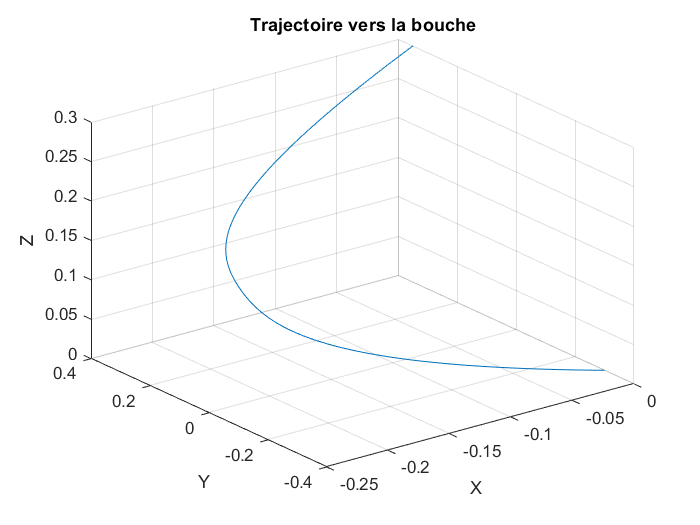

figure;
plot3(trajAvantBol2AvantBouche(1,:),trajAvantBol2AvantBouche(2,:),trajAvantBol2AvantBouche(3,:));
grid on;
title("Trajectoire vers la bouche");
xlabel("X");
ylabel("Y");
zlabel("Z");

Trajectoire   avantBouche --> avantBol

Paramètres

pointsTraj=[avantBouche(1)  -0.05 -0.25  -0.20  avantBol(1);
            avantBouche(2)   0.3   0.2   -0.2   avantBol(2);
            avantBouche(3)   0.1   0.05   0.00  avantBol(3)];
       
tInterval=[0 1];

tSamples=0:1/100:1;

[l,ld,ldd,pp] = bsplinepolytraj(pointsTraj,tInterval,tSamples);

trajAvantBouche2AvantBol=l;

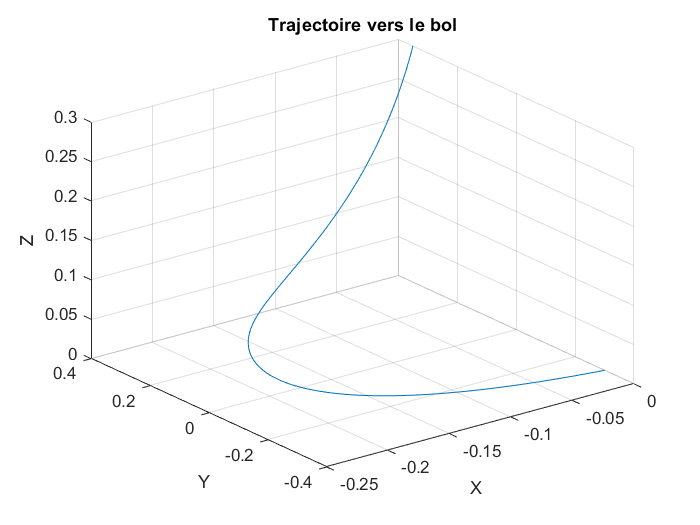

figure;
plot3(trajAvantBouche2AvantBol(1,:),trajAvantBouche2AvantBol(2,:),trajAvantBouche2AvantBol(3,:));
grid on;
title("Trajectoire vers le bol");
xlabel("X");
ylabel("Y");
zlabel("Z");

Trajectoire dépos nouriture 

freq=10;

trajAvantBouche2Bouche= ones(3,freq);
trajAvantBouche2Bouche(1,1)=avantBouche(1);
trajAvantBouche2Bouche(2,1)=avantBouche(2);
trajAvantBouche2Bouche(3,1)=avantBouche(3);

for i=1:0.5*freq
    trajAvantBouche2Bouche(1,i+1)=trajAvantBouche2Bouche(1,i);
    trajAvantBouche2Bouche(2,i+1)=trajAvantBouche2Bouche(2,i)+0.1/freq;
    trajAvantBouche2Bouche(3,i+1)=trajAvantBouche2Bouche(3,i);
end

for i=0.5*freq+1:1*freq
    trajAvantBouche2Bouche(1,i+1)=trajAvantBouche2Bouche(1,i);
    trajAvantBouche2Bouche(2,i+1)=trajAvantBouche2Bouche(2,i)-0.1/freq;
    trajAvantBouche2Bouche(3,i+1)=trajAvantBouche2Bouche(3,i);
end

Importation trajectoire Pelletage

M = transpose(readmatrix('PELLETAGEV4.xlsx'));
posePelletage=zeros(3,length(M));
anglePelletage=zeros(2,length(M));

for i=1:length(M)
    anglePelletage(1,i)=M(1,i);
    posePelletage(2,i)=-M(2,i)+(avantBol(2)-(-M(2,1)));
    posePelletage(3,i)=M(3,i)+(avantBol(3)-M(3,1));
    anglePelletage(2,i)=i-1;
    
    
end

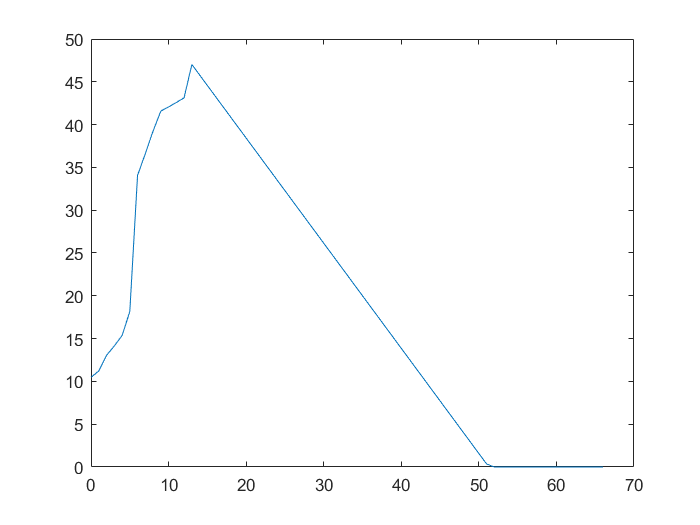

figure; 
plot(anglePelletage(2,:),anglePelletage(1,:));

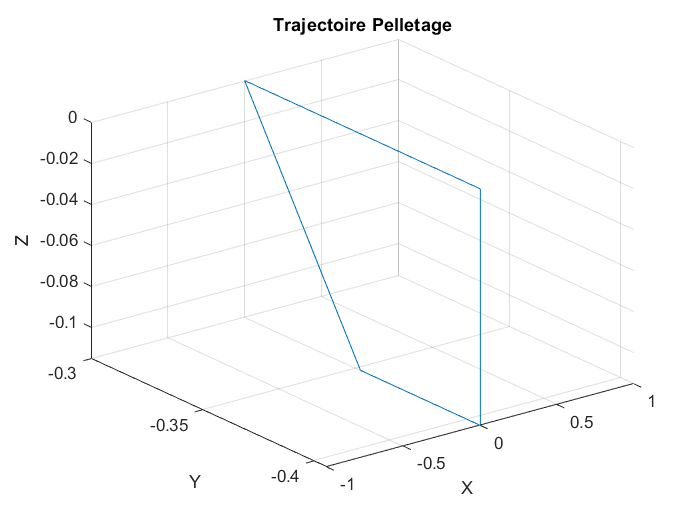

figure;
plot3(posePelletage(1,:),posePelletage(2,:),posePelletage(3,:));
title("Trajectoire Pelletage");
grid on;
xlabel("X");
ylabel("Y");
zlabel("Z");

l=[trajAvantBol2AvantBouche trajAvantBouche2Bouche trajAvantBouche2AvantBol posePelletage];

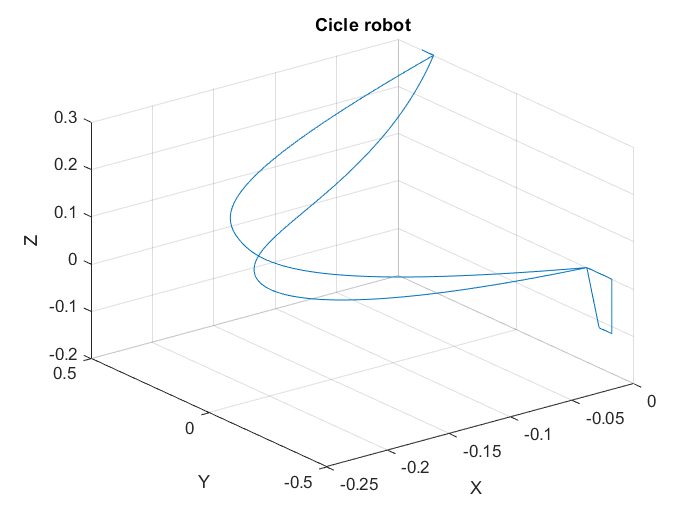

figure;
plot3(l(1,:),l(2,:),l(3,:));
grid on;
title("Cicle robot");
xlabel("X");
ylabel("Y");
zlabel("Z");

Fonction tau du temps

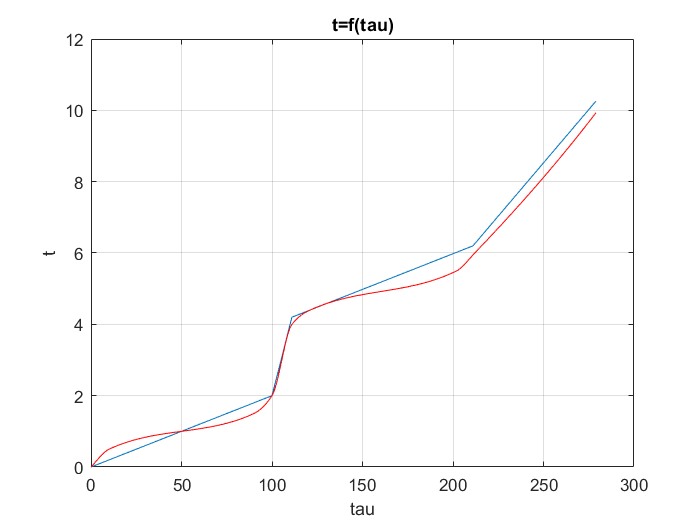

t=zeros(1,length(l));
tau=zeros(1,length(l));

for i=1:length(l)
    tau(i)=i-1;
end

for i=2:101
    tempsTrajet=2;
    t(i)=t(i-1)+tempsTrajet/100;
end

for i=102:112
    tempsTrajet=2;
    t(i)=t(i-1)+tempsTrajet/10;
end

for i=113:213
    tempsTrajet=2;
    t(i)=t(i-1)+tempsTrajet/100;
end

for i=213:length(l)
    tempsTrajet=4;
    t(i)=t(i-1)+tempsTrajet/(length(l)-213);
end

tauPoints=[0 10 90 100 111 121 202 212 280];
tPoints=[0 0.5 1.5 2 4 4.4 5.5 6 10];
t1=interp1(tauPoints,tPoints,tau,"pchip");

figure;
plot(tau,t,tau,t1,"r");
grid on;
title("t=f(tau)");
xlabel("tau");
ylabel("t");


tau=t1;

Abscisse curviligne

arc=zeros(4,length(l));
arc(1:3,:)=l;

arc(4,:)=tau;

Calcul de l'abscisse 

abs=zeros(2,length(arc)-1);

dx=arc(1,2)-arc(1,1);
dy=arc(2,2)-arc(2,1);
dz=arc(3,2)-arc(3,1);
abs(1,1)=sqrt(dx^2+dy^2+dz^2);


for i=2:length(arc)-1
    dx=arc(1,i+1)-arc(1,i);
    dy=arc(2,i+1)-arc(2,i);
    dz=arc(3,i+1)-arc(3,i);
    
    dAbs=sqrt(dx^2+dy^2+dz^2);
    
    abs(1,i)=abs(1,i-1)+dAbs;

end

abs(2,:)=tau(1:end-1);

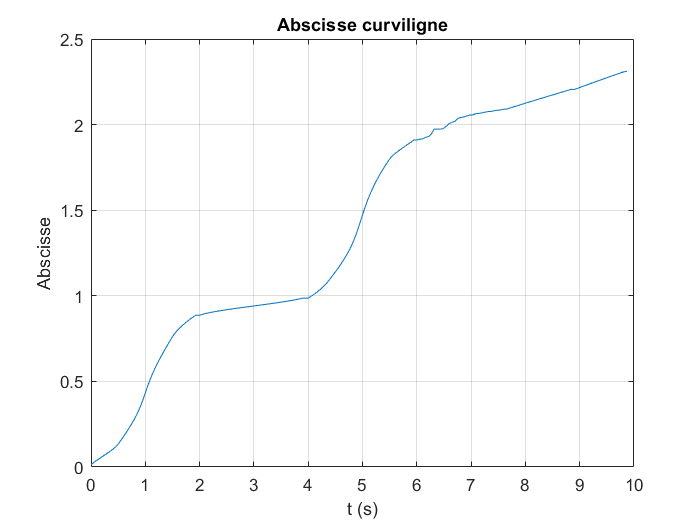

figure;
plot(abs(2,:),abs(1,:));
grid on;
title("Abscisse curviligne");
xlabel("t (s)");
ylabel("Abscisse");

Calcul de dAbs/dtau

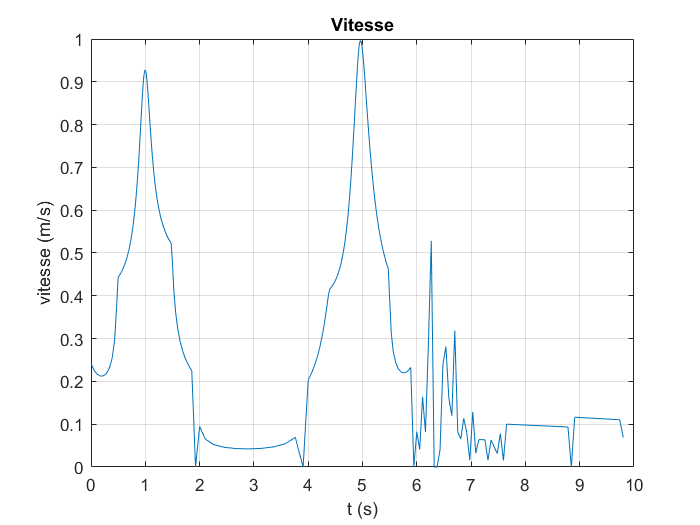

dAbs=zeros(2,length(abs)-1);
dAbs(1,:)=diff(abs(1,:))./diff(abs(2,:));
dAbs(2,:)=abs(2,1:end-1);

figure;
plot(dAbs(2,:),dAbs(1,:));
grid on;
title("Vitesse");
xlabel("t (s)");
ylabel("vitesse (m/s)");

Calcul de ddAbs/dtau

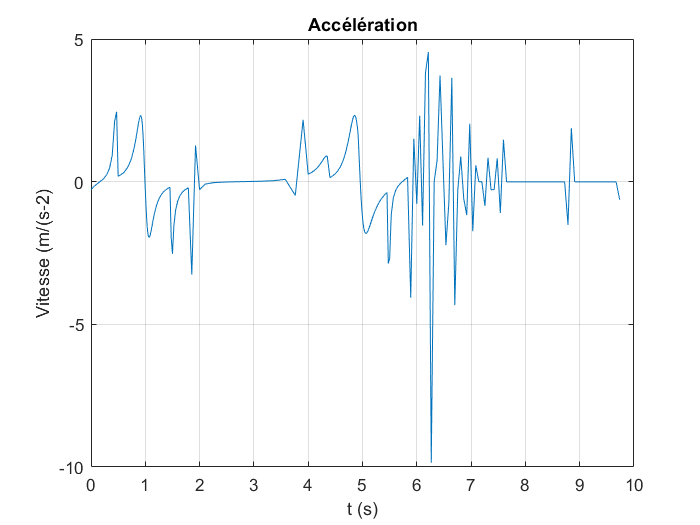

ddAbs=zeros(2,length(dAbs)-1);
ddAbs(1,:)=diff(dAbs(1,:))./diff(dAbs(2,:));
ddAbs(2,:)=dAbs(2,1:end-1);

figure;
plot(ddAbs(2,:),ddAbs(1,:));
grid on;
title("Accélération");
xlabel("t (s)");
ylabel("Vitesse (m/(s-2)");